# Chest Scan Image Pre-Processing

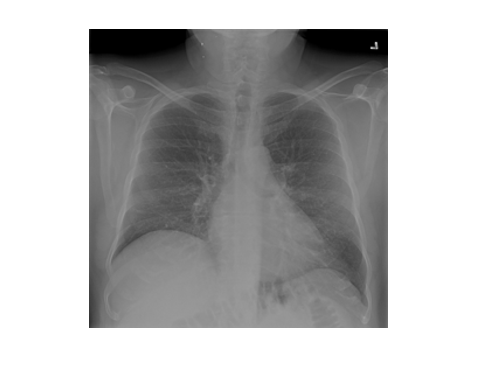

% Class - normal images
num_images = 2000; % Number of images in train dataset is 1-8000
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./train_data/normal/Normal-%i.png', i);
    img = (imread(filename));
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

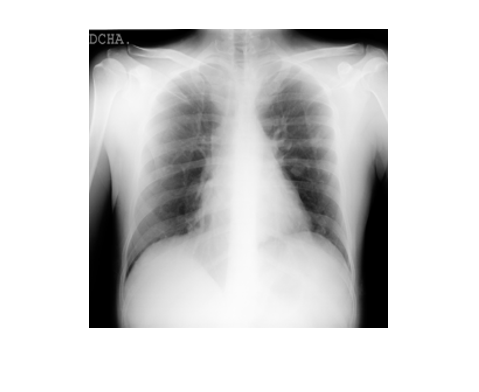

% Class - COVID
num_images2 = 1000; % Number of images in training dataset is 1-3000
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./train_data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img];
train_labels = labels;

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

% Create a model with standard params
Mdl = fitcecoc(Xnormk_train',train_labels_reduced');
% Note: This model performs poorly. More than 50% error when 
% tested using predict().

% Check inital error
error = resubLoss(Mdl)

error = 0.3200

% Cross validate, obtain better model performance
t = templateSVM('Standardize',true);
Mdl2 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'ClassNames',{'normal','COVID'});
% Mdl2 had about 85% accuracy when tested, much better than Mdl
options = statset('UseParallel',true);
CVMdl = crossval(Mdl2,'Options',options);
genError = kfoldLoss(CVMdl)

genError = 0.1217

% Return a vector of predicted values, should all be non-COVID.
% test data is 8001 - 8100
clear test_label_healthy; clear test_data_healthy; k = 1;
%test_data_healthy = zeros((299*299),(8100-8001+1));   % Initialize empty array
for i = 8001:8100
    filename = sprintf('./test_data/normal/Normal-%i.png', i);
    img = (imread(filename));
    test_data_healthy(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_healthy] = predict(CVMdl,test_data_healthy');

Check for missing argument or incorrect argument data type in call to function 'predict'.

% Check performance by counting number of times correct value was reached
perf_healthy_temp = categorical(test_label_healthy);
labels_perf = categories(perf_healthy_temp) % displlays labels

labels_perf = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_healthy = countcats(perf_healthy_temp) % displays occurance per label

perf_healthy =     11
    89


% E.g. for 11 COVID entries and 89 normal entries, the model is 89%
% accurate

% Return a vector of predicted values, should all be all COVID infections.
% test data is 3001 - 3100
clear test_label_covid; clear test_data_covid; k = 1;
%test_data_covid = zeros((299*299),(3101-3001+1));   % Initialize empty array
for i = 3001:3100
    filename = sprintf('./test_data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    test_data_covid(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_covid] = predict(CVMdl,test_data_covid');

Check for missing argument or incorrect argument data type in call to function 'predict'.

% Check performance by counting number of times correct value was reached
perf_covid_temp = categorical(test_label_covid);
labels_perf2 = categories(perf_covid_temp) % displlays labels

labels_perf2 = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_covid = countcats(perf_covid_temp) % displays occurance per label

perf_covid =     19
    81


% E.g. for 19 normal entries and 81 COVID entries, the model is 81%
% accurate